# NASA CEA Relation Plotter

Author: Kamon Blong ([kblong@purdue.edu](mailto:kblong@purdue.edu)) First Created: 10/23/2022 Last Updated:

8/22/2024 **Edited for Purdue Torch

%{
Description: Plots requested CEA outputs for given outputs - results are in
    displayed in metric
%}

clear;
clc;

CEA_input_name = 'plotcea';

## Assign Inputs

P_c = 200:25:500;            % chamber pressure [psi] ****(was 275)****
P_e = 14.7;           % exit pressure [psi]
OF = 1.3;             % OF ratio [N/A]
fuel = {'*H2'};  % fuel formula for NASA CEA
fuel_temp = [293.15];   % fuel temperature [K]
fuel_weight = 0;      % fuel weights, does nothing now
oxidizer = {'*O2'}; % oxidizer formula for NASA CEA
oxidizer_temp = 0;   % fuel temperature [K]
g = 1;          % gravitational constant [ft/s^2]

iterating_value = "OF";
min_value_OF = .2;
max_value_OF = 2;
step_value_OF = .05;

min_value_P_c = 50;
max_value_P_c = 350;
step_value_P_c = .5;

## Iterate Over CEA Values

counter = 1;

for P_c = 200:50:500
    if iterating_value == "OF"
    OF = min_value_OF;
    [c_star, isp, ~, ~, ~, P, T, ~, ~, ~, ~, ~, ~, ~] = RunCEA(P_c, P_e, fuel, fuel_weight, fuel_temp, oxidizer, oxidizer_temp, OF, 0, 0, 0, 1, 1, CEA_input_name);
    for OF = min_value_OF : step_value_OF : max_value_OF
        [c_star, isp, ~, ~, ~, P, T, ~, ~, ~, ~, ~, ~, ~] = RunCEA(P_c, P_e, fuel, fuel_weight, fuel_temp, oxidizer, oxidizer_temp, OF, 0, 0, 0, 1, 1, CEA_input_name);
        matrix(counter) = min_value_OF + step_value_OF * (counter - 1);
        T_matrix(counter) = T(1);
        isp_matrix(counter) = isp(1) / g;
        counter = counter + 1;
    end
end
end

## Plot Reults

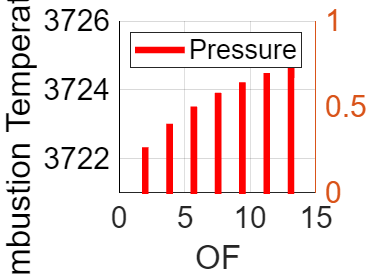

figure('Name', 'PlotCEA')
hold("on")

yyaxis left
plot(matrix, T_matrix, 'red','Linewidth', 4)
if iterating_value == "OF"
    xlabel('OF')
end
ylabel('Combustion Temperature [R]')
set(gca, 'Ycolor', 'k')

grid on
set(gca, 'FontSize', 18)
set(gca, 'XLim', [50, 350])
% set(gca, 'XLim', [0.3, 1.9])
legend('Pressure', 'Location', 'Northwest')

yyaxis left
ylim([3721 3726])
xlim([0 15])
% if iterating_value == "OF"
%     title(iterating_value + " plot:     " + fuel + " / " + oxidizer + " @ " + P_c + " psi P_c, " + P_e + " psi P_e")
% elseif iterating_value == "P_c"
%     title(iterating_value + " plot:     " + fuel + " / " + oxidizer + " @ " + OF + " OF ratio, " + P_e + " psi P_e")
% end

grid on